## Método CRP

(Siendo Gp= s+3/(s^3+5s^2+9s+5))

num=[1 3];
den=[1 5 9 5];
Gp=tf(num, den)


Gp =
 
          s + 3
  ---------------------
  s^3 + 5 s^2 + 9 s + 5
 
Continuous-time transfer function.
Model Properties


dt=0.05;
t=0:dt:8

t =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500


C=step(Gp, t)

C =          0
    0.0012
    0.0047
    0.0102
    0.0174
    0.0263
    0.0365
    0.0478
    0.0602
    0.0734


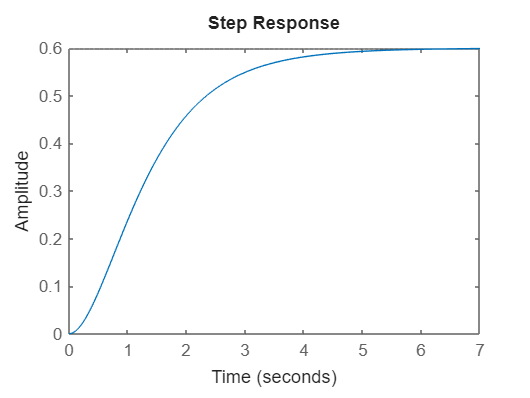

step(Gp)

dC=diff(C)/dt

dC =     0.0242
    0.0693
    0.1096
    0.1454
    0.1768
    0.2041
    0.2277
    0.2476
    0.2643
    0.2778


d2C=diff(dC)/dt;

figure(1)
plot(C, 'b')
hold on
plot(dC, 'r')
plot(d2C, 'g')
legend('C(t)', 'C''(t)', 'C''''(t)')
axis([0 100 -0.2 1])
grid

[m, p]=max(dC)

m = 0.3090

p = 16



L=0.2241

L = 0.2241

T=1.9418

T = 1.9418

Kp=1.2*T/L;
Ti=2*L;
Td=0.5*L;
Ki=Kp/Ti;
Kd1=Kp*Td;
Gc=tf([Kd Kp Ki], [1 0])


Gc =
 
  3.495 s^2 + 10.4 s + 23.2
  -------------------------
              s
 
Continuous-time transfer function.
Model Properties



FTLC1=feedback(Gc*Gp,1)


FTLC1 =
 
     3.495 s^3 + 20.88 s^2 + 54.39 s + 69.6
  --------------------------------------------
  s^4 + 8.495 s^3 + 29.88 s^2 + 59.39 s + 69.6
 
Continuous-time transfer function.
Model Properties


kp=1.5*Kp;
Kd=3*Kd1;
Gc=tf([Kd Kp Ki], [1 0])


Gc =
 
  3.495 s^2 + 10.4 s + 23.2
  -------------------------
              s
 
Continuous-time transfer function.
Model Properties



FTLC2=feedback(Gc*Gp,1)


FTLC2 =
 
     3.495 s^3 + 20.88 s^2 + 54.39 s + 69.6
  --------------------------------------------
  s^4 + 8.495 s^3 + 29.88 s^2 + 59.39 s + 69.6
 
Continuous-time transfer function.
Model Properties


kp=1.5*Kp;
Kd=5*Kd1;
Gc=tf([Kd Kp Ki], [1 0])


Gc =
 
  5.825 s^2 + 10.4 s + 23.2
  -------------------------
              s
 
Continuous-time transfer function.
Model Properties



FTLC3=feedback(Gc*Gp,1)


FTLC3 =
 
     5.825 s^3 + 27.87 s^2 + 54.39 s + 69.6
  --------------------------------------------
  s^4 + 10.83 s^3 + 36.87 s^2 + 59.39 s + 69.6
 
Continuous-time transfer function.
Model Properties


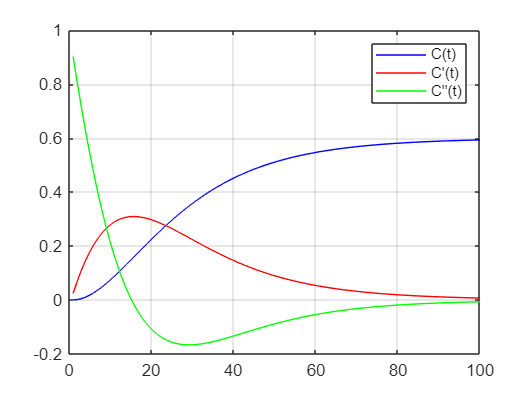

hold off //agregado porque sino aparecen lineas random

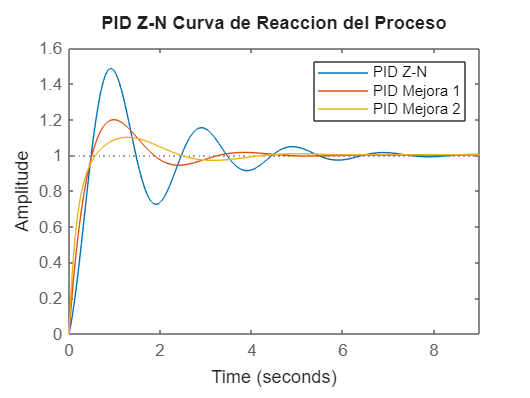

figure(2)
step(FTLC, FTLC2, FTLC3)
title('PID Z-N Curva de Reaccion del Proceso')
legend('PID Z-N', 'PID Mejora 1', 'PID Mejora 2')